DataOut = readtable("Data_Out.xlsx", Sheet="Coord")

DataOut = 168×4 table
     x      y       R        P   
    ____    __    _____    ______

    6000     0     0.54    589.05
    6000     5     0.54    588.16
    6000    10     0.54    587.24
    6000    15     0.54     586.3
    6000    20     0.54    585.35
    6000    25     0.54    584.37
    6000    30     0.54    583.38
    6000    35     0.54    582.37
    6000    40     0.54    581.34
    6000    45     0.54     580.3
    6000    50     0.54    579.23
    6000    55     0.54    578.16
    5000     0    0.575    570.14
    5000     5    0.575     569.1
    5000    10    0.575    568.04
    5000    15    0.575    566.97



[xq, yq] = meshgrid(0:3000, 0:50)

xq =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49
     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49
     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49
     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14  

yq =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2
     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3  

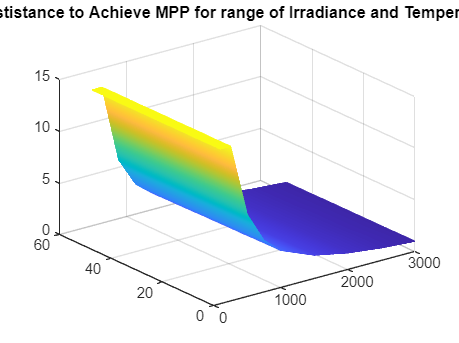

zq = griddata(DataOut.x, DataOut.y, DataOut.R, xq, yq );
mesh(xq, yq, zq)
hold on
%plot3(DataOut, "x", "y", "R");
title("Restistance to Achieve MPP for range of Irradiance and Temperature")

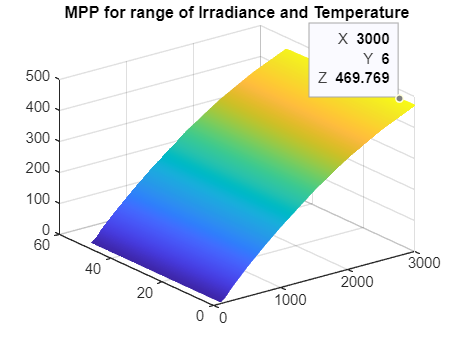

figure
zq = griddata(DataOut.x, DataOut.y, DataOut.P, xq, yq );
mesh(xq, yq, zq)
hold on
%plot3(DataOut, "x", "y", "P");
title("MPP for range of Irradiance and Temperature")